# 自分の Qiita 記事の閲覧数順リストを GitHub Actions で自動定期更新

## やったこと

GitHub Actions で何か自動化したいな～・・と思い立って。

幸い GitHub-hosted runner でも Public repo に限ってですがライセンス不要！ MATLAB もサポートされている（[MATLAB Actions](https://github.com/matlab-actions)、解説動画：[YouTube: Using MATLAB with GitHub Actions](https://www.youtube.com/watch?v=Qj5upV0Qm1o)）ので、以下の処理を自動定期実行させてみました。

- Qiita API で自分の投稿を収集

- 閲覧数を確認して1か月前との差分（一か月間の閲覧数）を確認

- 1か月間の閲覧数順に投稿をソート

- リスト化して記事更新

各ステップを解説します。

- コードはこちら：GitHub [minoue-xx / qiita-track-page-view-counts-of-your-article](https://github.com/minoue-xx/qiita-track-page-view-counts-of-your-article)

- 実行結果：[これまでの投稿まとめ：閲覧数順一覧（yyyy/mm/dd更新）](https://qiita.com/eigs/items/ce39353181fee616d52e)

#### ハマりポイント

GitHub の場合 repo に workflow を含むかどうか、Qiita API の場合は書き込みするかどうかで Token 作成時の設定が異なるので要注意。

### 参考

Qiita への記事投稿については [Qiita: MATLABでQiitaへ記事を投稿してみた](https://qiita.com/kikd/items/5196b3a46e291a3666fc) が参考になりました。 [@kikd](https://qiita.com/kikd) さんありがとうございます！また Qiita API を使った投稿記事の収集については[【COTOHA API x MATLAB】Qiita 投稿記事の要約](https://qiita.com/eigs/items/39196afdb5f28bf3ba0f) でも紹介しています。

#### 実行環境

- MATLAB R2022a

- Text Analytics Toolbox

## 1. Qiita API で自分の投稿を収集

まずは [Qiita API](https://qiita.com/api/v2/docs) 等の設定ですね。 GET /api/v2/users/:user_id/items で指定されたユーザーの記事一覧を、作成日時の降順で返します。

アクセストークンは事前に環境変数に設定しておいた体で進めます。GitHub Actions で使用する時は Settings -> Secrets -> Actions から Repository secrets として設定しておき、workflow で環境変数として指定します。（Environment secrets に設定すればよかったかな？）

accessToken=getenv('QIITAACCESSTOKEN'); 
user_id = "eigs"; % Qiita id
baseurl = "https://qiita.com/api/v2"; % Qiita API base URL
articleuri = 'https://qiita.com/api/v2/items/ce39353181fee616d52e'; % 結果の投稿先
opts = weboptions('HeaderFields',{'Authorization',accessToken});
per_page = 20;

自分（@eigs）の記事を取ってきます。

注：Qiita API では自分自身の投稿しか閲覧数（page_views_count）を確認できないようです。

いま何が起こっているかが確認できると安心なのでところどころに disp を設定しておきます。

disp("Extracting article data started...") 

Extracting article data started...


index = 1;
item_list = table; % table to add items
nItems = per_page; % 一度に per_page 記事取得（max 100）
while nItems == per_page
    url = baseurl + "/users/" + user_id + "/items?page="...
        + index + "&per_page=" + per_page;
    tmp = webread(url,opts);

    index = index + 1; % counter

    % 必要な情報だけ確保しておきます。
    id = string(vertcat(tmp.id));
    title = string({tmp.title})';
    tags = {tmp.tags}';
    rendered_body = string({tmp.rendered_body})';
    url = string(vertcat(tmp.url));
    page_views_count = vertcat(tmp.page_views_count);
    likes_count = vertcat(tmp.likes_count);
    created_at = datetime(vertcat(tmp.created_at),...
        'InputFormat', "uuuu-MM-dd'T'HH:mm:ss'+09:00"); % datetime に変換も大事

    % table 型に成形
    nItems = length(id);
    tmp = table(created_at, id, title, tags, likes_count, url, ...
        page_views_count, rendered_body, ...
        'VariableNames',{'created_at','id','title','tags','likes_count','url',...
        'page_views_count','rendered_body'});

    % append
    item_list = [item_list; tmp];
end

一覧でまとめたときにタイトルだけでは寂しいので、記事の最初の一文も取っておきます。意外と中身を理解（or 想像）するのに役立ちます。getFirstSentence 関数はページ下部で定義しています。

firstSentence = strings(height(item_list),1);
for ii=1:height(item_list)
    firstSentence(ii) = getFirstSentence(item_list.rendered_body(ii));
end
item_list.firstSentence = firstSentence;
item_list = removevars(item_list,"rendered_body");
disp("Extracting article data completed.")
head(item_list)

Extracting article data completed.


これで記事抽出完了！

## 2. 閲覧数を確認して1か月前との差分（一か月間の閲覧数）を確認

初回実行時には過去の情報がないので、viewHistory.csv に記事の id と page_views_count を保存して、ここで処理は終了で次の実行を待ちます。2回目以降は保存しておいた viewHistory.csv から各記事毎に差分を確認します。

注：GitHub Actions 実行環境との local setting の違いで時刻データがうまく認識されない事がありますので要注意

期間中に新しく投稿された記事があると多少ややこしくないますが、その辺は outerjoin を使ってさくっと新しいデータとマージしておきます。

viewsHistory = rows2vars(item_list(:,["id","page_views_count"]),...

ans = 8×8 table
        created_at                   id                                          title                                     tags        likes_count                            url                            page_views_count                                                                                                                                                   firstSentence                                                                                                                                                
    ___________________    ______________________    ______________________________________________________________    ____________    ___________    ___________________________________________________    ________________    _________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    'VariableNamesSource','id','VariableNamingRule','preserve');
viewsHistory = removevars(viewsHistory,'OriginalVariableNames');
tViewsHistory = table2timetable(viewsHistory,"RowTimes",datetime);

if ~exist("viewsHistory.csv","file") % 初回実行時
    writetimetable(tViewsHistory,"viewsHistory.csv");
    disp("Data is saved to viewsHistory.csv");
    disp("Only one observation is available. Need at least two points...");
    disp("Process Completed.")
    return; % ここで終了
else
    tmp = readtable("viewsHistory.csv",...
        ReadVariableNames=true, VariableNamingRule='preserve');

    % If the datetime string was not correctly parsed (due to locale setting)
    if iscell(tmp.Time)
        tmp.Time = datetime(tmp.Time,'Locale','en_US');
    end
    % add a new data point
    tmp = outerjoin(tmp, timetable2table(tViewsHistory),MergeKeys=true);
    tViewsHistory = table2timetable(tmp,"RowTimes",'Time');
    writetimetable(tViewsHistory,"viewsHistory.csv");
    disp("Data is saved to viewsHistory.csv");
end

Data is saved to viewsHistory.csv


1か月前との差分を確認して、item_list に加えます。

viewsHistory = rows2vars(tViewsHistory,"VariableNamingRule","preserve");
% Article ID = OriginalVariableNames by this operation
viewsHistory.OriginalVariableNames = string(viewsHistory.OriginalVariableNames);
% get the difference from the previous data point
viewsHistory.dviews = viewsHistory{:,end}-viewsHistory{:,end-1};

item_list = join(item_list,viewsHistory,...
    'LeftKeys','id',...
    'RightKeys','OriginalVariableNames',...
    'RightVariables','dviews');

period0 = tViewsHistory.Time(end-1);
period1 = tViewsHistory.Time(end);

% set format for display
period0.Format = "yyyy/MM/dd";
period1.Format = "yyyy/MM/dd";

## 3. 1か月間の閲覧数順に投稿をソート

上で確認した過去の閲覧数との差分（前回実行時からの閲覧数）順に記事を並べ替えて、投稿用の markdown を作成します。

ソートは sortrows で。

item_list = sortrows(item_list,{'dviews','page_views_count'},'descend','MissingPlacement','last');

markdown で投稿文を作ります。まずは冒頭の定型文として、集計方法やら対象期間やらを埋めておきます。

header = "これまでの投稿を過去一か月の閲覧数順に並べています。" + newline ...
    + "# 集計方法" + newline ...
+ "期間: " + string(period0) + " ~ " + string(period1) + newline ...
+ "対象: @" + user_id + " の投稿" + "（ " + height(item_list) + " 投稿）" + newline ...
+ "詳細: [GitHub: Qiita Track Page View Counts of Your Articles]" ...
+ "(https://github.com/minoue-xx/qiita-track-page-view-counts-of-your-article)" + newline ...
+ newline ...
+ "作成にあたって以下を参考にいたしました。@kikd さんありがとうございます！" + newline ...
+ " - [GitHub: kikd/matlab-post-qiita](https://github.com/kikd/matlab-post-qiita)" + newline ...
+ " - [Qiita: MATLABでQiitaへ記事を投稿してみた](https://qiita.com/kikd/items/5196b3a46e291a3666fc)";

こんな感じ。そして記事本文を header に追加します。

md = generateMarkdown_ver2(item_list, header);

generateMarkdown_ver2 関数はページ下部に定義していますが、やっていることは記事のタイトル、閲覧数、LGTM 数、投稿日時や tag 情報を順番に並べて行く作業です。

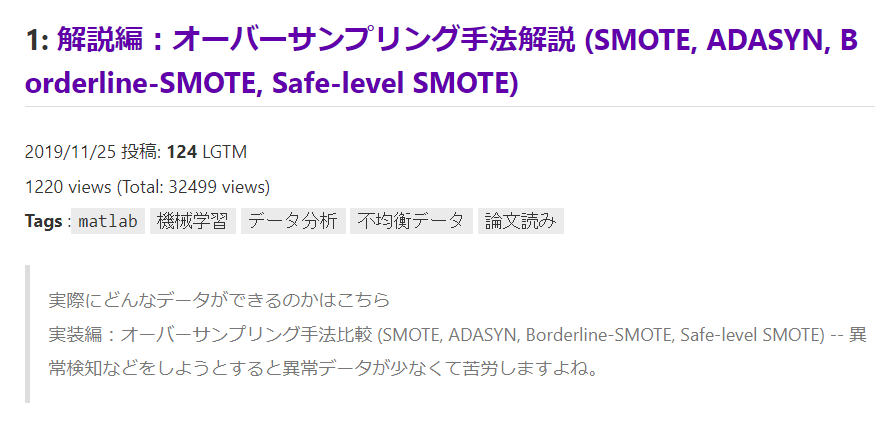

投稿内容の最初の一文も入れるとこんな形になります。

## 4. リスト化して記事更新

初回投稿であれば POST /api/v2/items ですが、今回のように既存の記事を更新する場合は PATCH /api/v2/items/:item_id を使います。細かいところは [@kikd](https://qiita.com/kikd) さんの [Qiita: MATLABでQiitaへ記事を投稿してみた](https://qiita.com/kikd/items/5196b3a46e291a3666fc) をマネさせてもらっています。

tags = ["matlab" "QiitaAPI" "RestAPI"]; % tag 設定
tag_count = length(tags);
if(tag_count > 5)
    error("タグが多すぎます");
end
article_tag = {tag_count}; % 深い意図はなし。変数定義。
for i = 1:tag_count
    article_tag{i} = struct('name', tags{i});
    display(article_tag{i})
end

タイトル、記事本文を設定。

article_title = "これまで投稿：閲覧数順一覧 (" + string(period1) + "更新)";
article_body = struct("body",md, "private", false, ...
    "tags", {article_tag}, "title",article_title, "tweet", false);


APIの指定とヘッダの設定。最初の方で取得したトークンをAuthorizationヘッダにつける。

webopt = weboptions(...
    'ContentType', 'json',...
    'RequestMethod', 'patch', ...
    'HeaderFields', {'Authorization' accessToken}...
    );

webwrite で更新。

try
    response = webwrite(articleuri, article_body, webopt);
    disp("Article updated at" + response.url);
catch ME
    disp("Error: " + ME.identifier);
end

これで出来上がり。

### 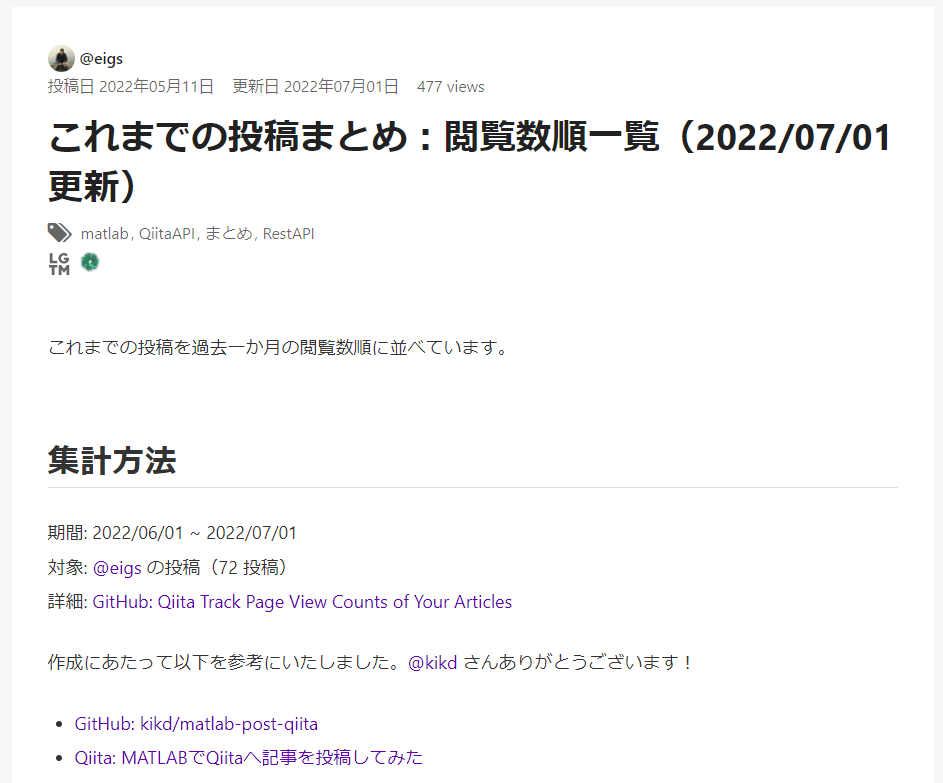

## 最後に・・Workflow を定義して定期実行！

月初めに実行されるように設定している workflow ファイルは[こちら](https://github.com/minoue-xx/qiita-track-page-view-counts-of-your-article/blob/main/.github/workflows/main.yml)を見てください。

ポイントとしては

と環境変数を定義しての MATLAB スクリプトの実行と、実行のたびに更新される viewsHistory.csv を commit する以下の処理です。

### Appendix A. generateMarkdown 関数

やっていることは記事のタイトル、閲覧数、LGTM 数、投稿日時や tag 情報を順番に並べて行く作業です。

function md = generateMarkdown_ver2(tData, header)

md = header + newline + newline;
for ii=1:height(tData)
    title = tData.title(ii);
    url = tData.url(ii);
    md = md + "## " + ii + ": [" + title + "]("+url+")" + newline;
    likes = tData.likes_count(ii);
    date = tData.created_at(ii);
    views = tData.page_views_count(ii);
    dviews = tData.dviews(ii);
    date.Format = 'yyyy/MM/dd';

    if isnan(dviews)
        dviews = "NaN";
    end

    md = md + string(date) + " 投稿" + ": **" + string(likes) + "**" + " LGTM" ...
        + newline ...
        + dviews + " views (Total: " + views + " views)" + newline;

    tags = tData.tags{ii};
    tags = string({tags.name});
    tags = "```" + tags + "```";
    md = md + "**Tags** :" + join(tags) + newline;

    summary = tData.firstSentence(ii);
    if strlength(summary) > 150 % 長い場合は打ち切っちゃいます。
        tmp = char(summary);
        summary = string(tmp(1:150)) + "...(中略)";
    end
    md = md + newline + ...
        "> " + summary + newline + newline;
end

end


### Appendix B. getFirstSentence 関数

Qiita の html ソースから記事の最初の一文を取り出す関数

function sentence = getFirstSentence(htmlSource)

tree = htmlTree(htmlSource);

% selector = "h1,h2,h3,p,li";
selector = "p,li";
subtrees = findElement(tree,selector);

% check if details contained in p
index = false(length(subtrees),1);
for ii=1:length(subtrees)
    tmp = findElement(subtrees(ii),'details');
    index(ii) = isempty(tmp); % <DETAILS> があれば false になる
end

% DETAILS 無しの P, LI だけ
subtreesNoDetails = subtrees(index);

% 入力文
sentence = extractHTMLText(subtreesNoDetails);

sentence = join(sentence);
tmp = split(sentence(1),'。');
sentence = tmp(1) + "。";

end